clc;
clear;close all;

# Correct Symbol Timing Error of QPSK-Modulated Signal

Correct a fixed symbol timing error on a noisy QPSK-modulated signal. Check the bit error rate (BER) of the synchronized received signal.

Initialize simulation parameters.

M = 4;         % Modulation order for QPSK
nSym = 32000;   % Number of symbols in a packet
sps = 100;       % Samples per symbol
timingErr = 2; % Samples of timing error
snr = 45;      % Signal-to-noise ratio (dB)
fc=1e6;
fs=1e7;

Create root raised cosine (RRC) transmit and receive filter System objects.

txfilter = comm.RaisedCosineTransmitFilter( ...
    OutputSamplesPerSymbol=sps);
rxfilter = comm.RaisedCosineReceiveFilter( ...
    InputSamplesPerSymbol=sps, ...
    DecimationFactor=sps/4);

data = randi([0 M-1],nSym,1);
modSig = pskmod(data,M,pi/4);

t=0:1/fs:(length(data)*sps-1)/fs;
txSig = abs(txfilter(modSig).*exp(1i*2*pi*fc*t.'));
txSig1 = txfilter(modSig).*exp(1i*2*pi*fc*t.');
% delaySig = fixedDelay(txSig);

Pass the delayed signal through an AWGN channel with a 15 dB signal-to-noise ratio.

rxSig = awgn(txSig,snr,'measured');

Filter the modulated signal through a receive RRC filter by using the `rxfilter` object. Display the scatter plot. Due to the timing error, the received signal does not align with the expected QPSK reference constellation.

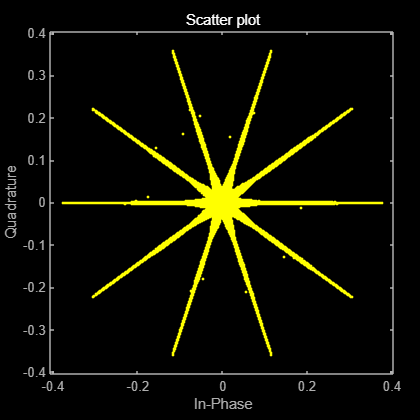

% rxdata=readmatrix("111.csv");
% Idata=rxdata(:,1);
% Qdata=rxdata(:,2);
% plot(Idata,"r");hold on;
% plot(Qdata,"g");hold off;


% t=0:1/fs:(length(Idata)-1)/fs;
 I_demod=2*txSig.*cos(2*pi*fc*t.');
 Q_demod=-2*txSig.*sin(2*pi*fc*t.');

% 低通滤波去除高频分量
lpFilt = designfilt('lowpassfir', 'FilterOrder', 100, ...
    'CutoffFrequency', 1.3e6, 'SampleRate', fs);

I_baseband = filtfilt(lpFilt, I_demod);
Q_baseband = filtfilt(lpFilt,  Q_demod);

% I_baseband = I_demod;
% Q_baseband =  Q_demod;
% 组合为复基带信号
rx_baseband = I_baseband + 1j * Q_baseband;
rx_baseband1 =txSig1.*exp(-1i*2*pi*fc*t.');
scatterplot(rx_baseband);

fprintf('正交解调完成\n');

正交解调完成



%% 6. 匹配滤波
fprintf('\n6. 匹配滤波...\n');


6. 匹配滤波...


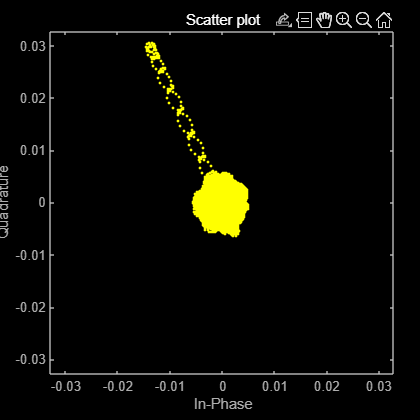

rcrFilt = comm.RaisedCosineReceiveFilter(...
    'Shape', 'Square root', ...
    'RolloffFactor', 0.35, ...
    'FilterSpanInSymbols', 6, ...
    'InputSamplesPerSymbol', sps, ...
    'DecimationFactor', 1);
a=rcosdesign(0.35,6,sps,"sqrt");
i=conv(a,I_baseband);
q=conv(a,Q_baseband);
rx_filtered=i+j*q;
scatterplot(rx_filtered );

% % 使用相同的根升余弦滤波器进行匹配滤波
% rx_filtered = conv(rx_baseband, rrcFilter, 'same');
% rx_filtered = rcrFilt(rx_baseband);
rx_filtered1 = rcrFilt(rx_baseband1);
symbolSync = comm.SymbolSynchronizer;
groupDelay=6*sps/2;
% rx_filtered= symbolSync (rx_filtered);       
rx_filtered = rx_filtered(2*groupDelay+1:end);

% plot(real(rx_filtered));
% plot(imag(rx_filtered));
% 下采样到符号率
start=600;
rx_symbols = rx_filtered1(start:sps:end);
scatterplot(rx_symbols );
scatterplot(rx_filtered(1:sps:end) );






rxSig=rxSig(300:end-300);
rxSample = rxfilter(rxSig);  
% scatterplot(rxSample(1001:end),2)
cc=abs(abs(real(rxSample))-abs(real(rxSample)));
a=min(cc(1:4));
s1=(1+1i*1)/(sqrt(2));
s2=(1+1i*-1)/(sqrt(2));
s3=(-1+1i*1)/(sqrt(2));
s4=(-1-1i*1)/(sqrt(2));
rx=[];
dis1=0.8;
for i=1:length(rxSample)   
   v1=dist(rxSample(i),s1);
   if v1<dis1
       rx=[rx rxSample(i)];
       continue;
   end
    v2=dist(rxSample(i),s2);
   if v2<dis1
       rx=[rx rxSample(i)];
       continue;
   end
     v3=dist(rxSample(i),s3);
   if v3<dis1
       rx=[rx rxSample(i)];
       continue;
   end
  v4=dist(rxSample(i),s4);
   if v4<dis1
       rx=[rx rxSample(i)];
       continue;
   end


end
start=15;
scatterplot(rxSample(start:sps:end));
rxSync = symbolSync(rxSample);
scatterplot(rxSync(11:end))

scatterplot(rx)
%%%%%%%%%%%%%%%%%%%%%%%%%计算两个点之间距离%%%%%%%%%%%
function distance=dist(a,b)
x1=real(a);
y1=imag(a);
x2=real(b);
y2=imag(b);
distance=sqrt((x1-x2).^2+(y1-y2).^2);
end